# Automate Ground Truth Labeling of Lane Boundaries

This example shows how to develop an algorithm for the automated marking of lane boundaries in the [Ground Truth Labeler](docid:driving_ref#bvie3n7-1) app. 

## The Ground Truth Labeler App

Good ground truth data is crucial for developing driving algorithms and evaluating their performances. However, creating a rich and diverse set of annotated driving data requires significant time and resources. The [Ground Truth Labeler](docid:driving_ref#bvie3n7-1) app makes this process efficient. You can use this app as a fully manual annotation tool to mark lane boundaries, vehicle bounding boxes, and other objects of interest for a vision system. However, manual labeling requires a significant amount of time and resources. This app also provides a framework to create algorithms to extend and automate the labeling process. You can use the algorithms you create to quickly label entire data sets, and then follow it up with a more efficient, shorter manual verification step. You can also edit the results of the automation step to account for challenging scenarios that the automation algorithm might have missed. This example describes how to insert a lane detection algorithm into the automation workflow of the app.

## Create a Lane Detection Algorithm

First, create a lane detection algorithm. The [Visual Perception Using Monocular Camera](docid:driving_ug#mw_b13b3ce9-9de9-4d94-a014-13a01f2ca568) example describes the process of detecting lane boundaries, and the [`helperMonoSensor`](matlab:openExample('driving/AutomateLabelingOfLaneBoundariesExample','supportingFile','helperMonoSensor.m')) class packages that algorithm into a single, reusable class. Try out the algorithm on a single video frame to detect the left ego lane boundary.

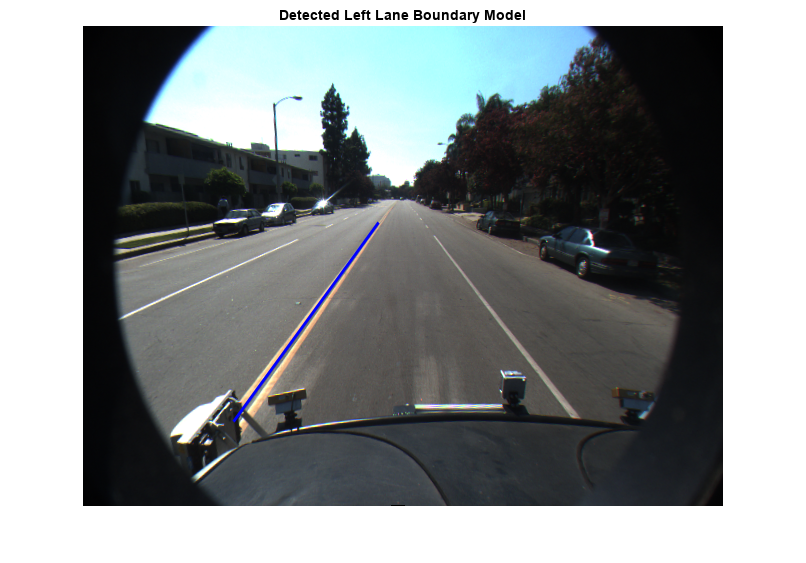

configData = load('birdsEyeConfig');
sensor     = configData.birdsEyeConfig.Sensor;
monoSensor = helperMonoSensor(sensor);
I          = imread('road.png');

sensorOut = processFrame(monoSensor, I);
lb = sensorOut.leftEgoBoundary;
figure
IwithLane = insertLaneBoundary(I, lb, sensor, [3 30], 'Color', 'blue');
imshow(IwithLane);
title('Detected Left Lane Boundary Model');

## Mark Lane Boundary Points

The lane detected in the previous step is a *model* and must be converted to a set of discrete points. These points are similar to what a user might manually place on the image. In the camera view, parts of the lane boundary closer to the vehicle (lower part of the camera image) will span more pixels than the further parts. Consequently, a user would place more points with higher confidence in the lower parts of the camera image. To replicate this behavior, determine the lane boundary locations from the boundary model more densely at points closer to the vehicle.

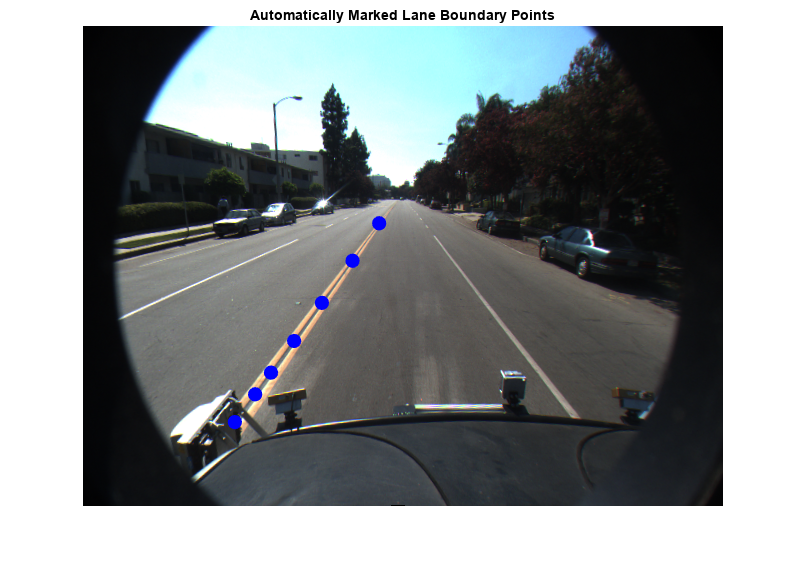

ROI      = [3 30];
xPoints  = [3 3.5 4 5 7 12 30]'; % More dense closer to the vehicle
yPoints  = lb.computeBoundaryModel(xPoints);

% Find corresponding image locations.
boundaryPointsOnImage = vehicleToImage(sensor, [xPoints, yPoints]);

imshow(I)
hold on
plot(boundaryPointsOnImage(:,1), boundaryPointsOnImage(:,2),...
    'o',...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor','b',...
    'MarkerSize',10)
title('Automatically Marked Lane Boundary Points');
hold off

## Integrate Lane Detection Algorithm Into Ground Truth Labeler

To incorporate this lane detection algorithm into the automation workflow of the app, construct a class that inherits from the abstract base class [`vision.labeler.AutomationAlgorithm`](docid:vision_ref#bvk0cv0-1). This base class defines properties and signatures for methods that the app uses for configuring and running the custom algorithm. The Ground Truth Labeler app provides a convenient way to obtain an initial automation class template. For details, see [Create Automation Algorithm for Image Labeling](docid:vision_ug#mw_6502f53f-e66e-4aaa-bf73-34a8d84284c5). The [`AutoLaneMarking`](matlab:edit('AutoLaneMarking');) class is based off of this template and provides you with a ready-to-use automation class for lane detection. The comments of the class outline the basic steps needed to implement each API call.

Step 1 contains properties that define the name and description of the algorithm, and the directions for using the algorithm.

Step 2 contains the custom properties needed for the core algorithm. The necessary properties were determined from the lane detection and lane point creation section above.

Step 3 deals with function definitions. The first function, `checkLabelDefinition`, ensures that only labels of the appropriate type are enabled for automation. For lane detection, you need to ensure that only labels of type `Line` are enabled, so this version of the function checks the `Type` of the labels:

The next function is `checkSetup`. Note that this algorithm *requires* a `monoCamera` sensor configuration to be available. All other properties have defined reasonable defaults.

Next, the `settingsDialog` function obtains and modifies the properties defined in Step 2. This API call lets you create a dialog box that opens when a user clicks the **Settings** button in the **Automate** tab. To create this dialog box, use the [`inputdlg`](docid:matlab_ref#f44-13429) function to quickly create a simple modal window to ask a user to specify the `monoCamera` object. The following snippet of code outlines the basic syntax. The full [`AutoLaneMarking`](matlab:edit('AutoLaneMarking');) code extends this logic and also adds input validation steps.

Step 4 specifies the execution functions. Some automation algorithms need to implement an `initialize` routine to populate the initial algorithm state based on the existing labels in the app. This lane detection algorithm works on each frame independently, so the default version of the template has been trimmed to take no action.

Next, the `run` function defines the core lane detection algorithm of this automation class. `run` gets called for each video frame, and expects the automation class to return a set of labels. The `run` function in [`AutoLaneMarking`](matlab:edit('AutoLaneMarking');) contains the logic introduced previously for the lane detection and conversion to points. Code from [`helperMonoSensor`](matlab:openExample('driving/AutomateLabelingOfLaneBoundariesExample','supportingFile','helperMonoSensor.m')) has also been folded in for a more compact reference.

Finally, the `terminate` function handles any cleanup or tear-down required after the automation is done. This algorithm does not require any cleanup, so the function is empty.

## Use the AutoLaneMarking Automation Class in the App

The packaged version of the lane detection algorithm is now ready for use in the [`AutoLaneMarking`](matlab:edit('AutoLaneMarking');) class. To use this class in the app:

- Create the folder structure required under the current folder, and copy the automation class into it.

- Load the [`monoCamera`](docid:driving_ref#bvgu10o-1) information into the workspace.

- Open the [Ground Truth Labeler](docid:driving_ref#bvie3n7-1) app.

- On the left pane, click the **Define new ROI label** button and define the ROI line style shown. Then click OK.

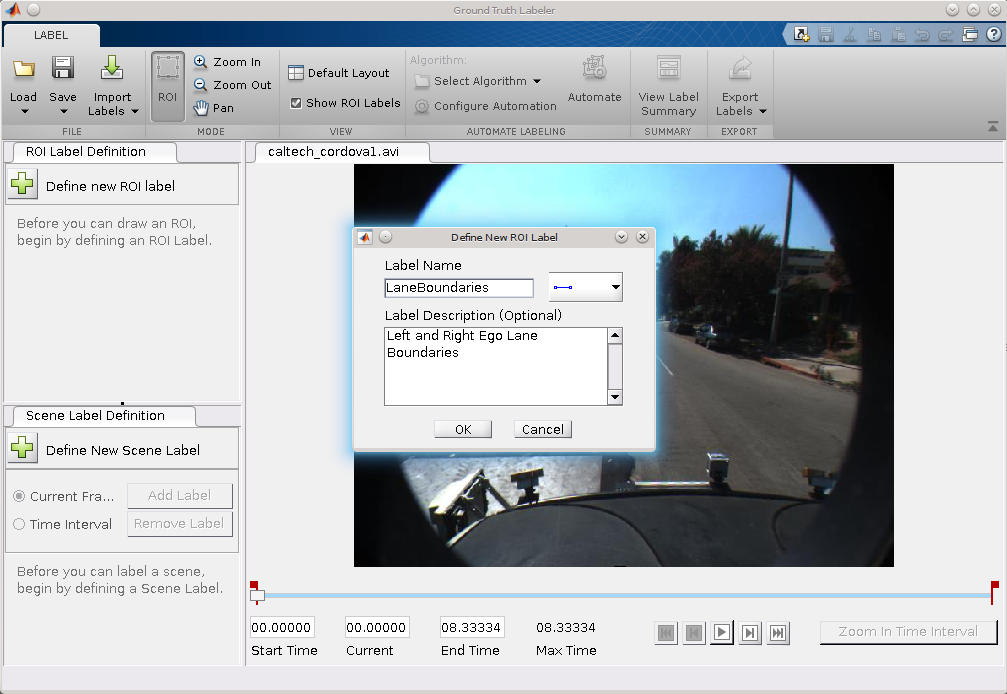

- Click  **Algorithm > Select Algorithm > Refresh list**.

- Click  **Algorithm > Auto Lane Detection**. If you do not see this option, ensure that the current working folder has a folder called `+vision/+labeler`, with a file named `AutoLaneMarking.m` in it.

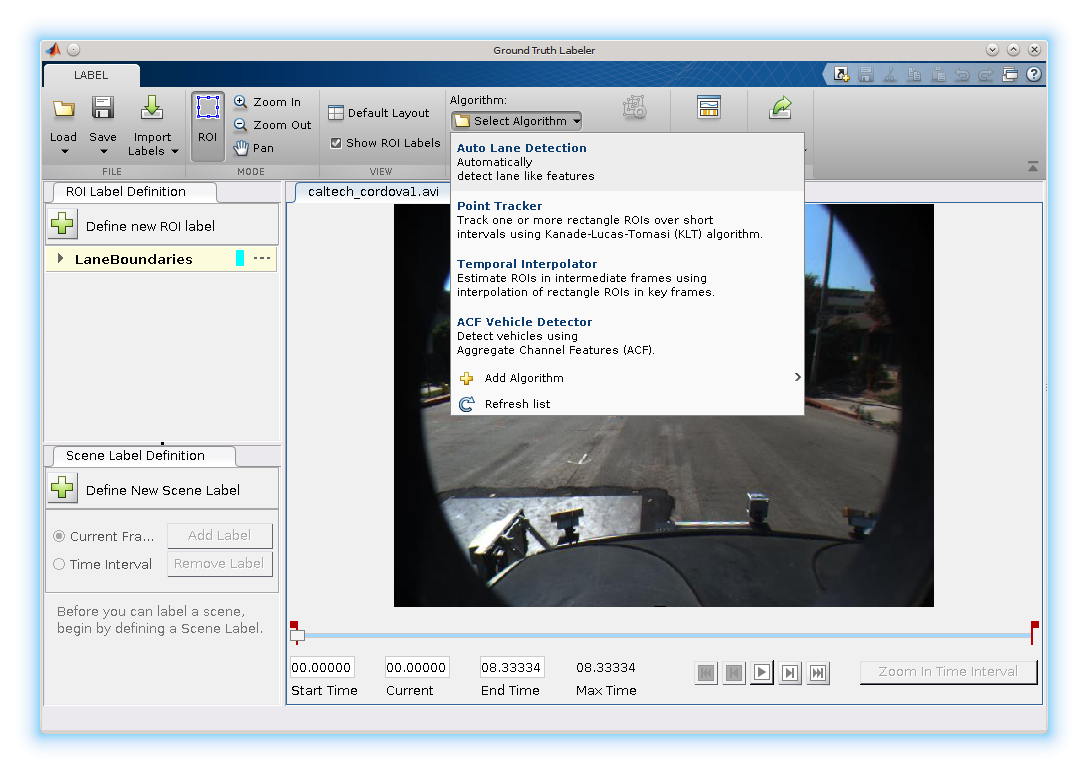

- Click **Automate**. A new tab will open, displaying directions for using the algorithm.

- Click **Settings**, and in the dialog box that opens, enter `sensor` in the first text box. Modify other parameters if needed before clicking **OK**.

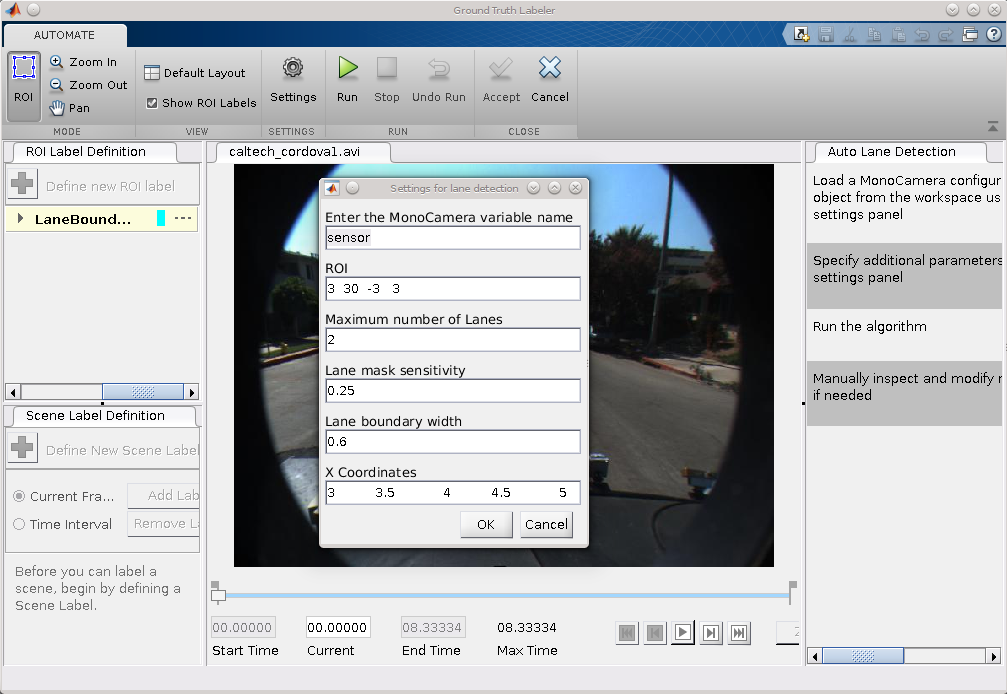

- Click **Run**. The lane detection algorithm progresses on the video. Notice that the results are not satisfactory in some of the frames.

- After the run is completed, use the slider or arrow keys to scroll across the video to locate the frames where the algorithm failed.

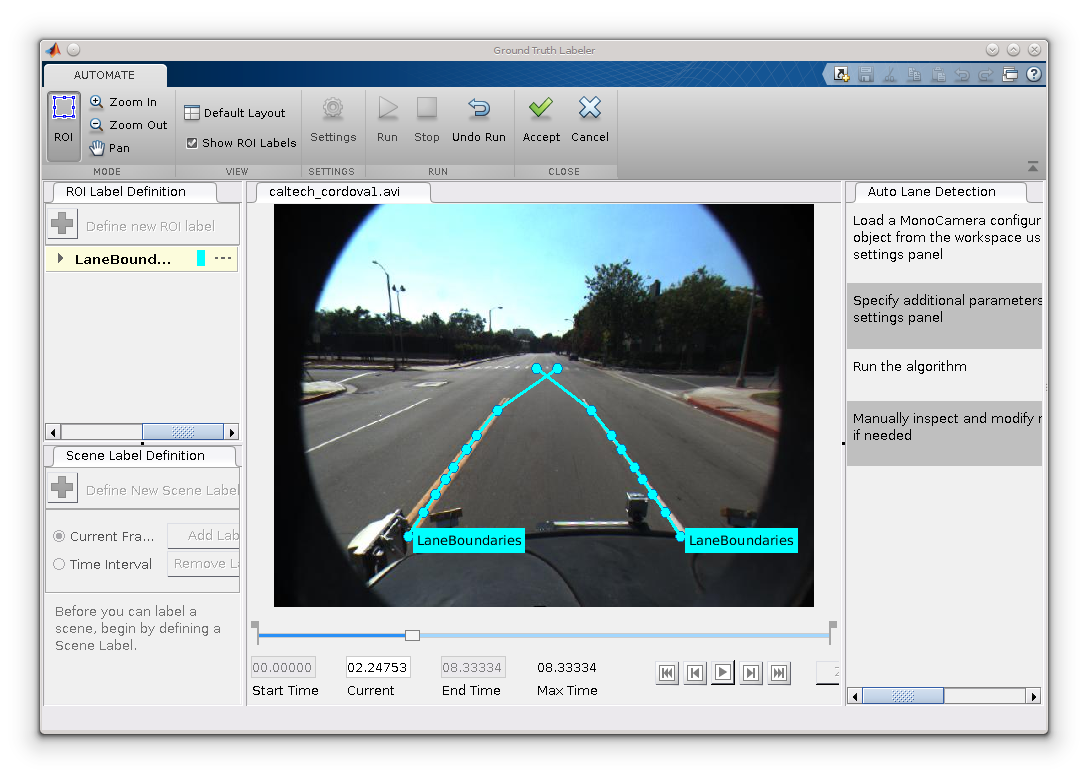

- Manually tweak the results by either moving the lane boundary points or deleting entire boundaries.

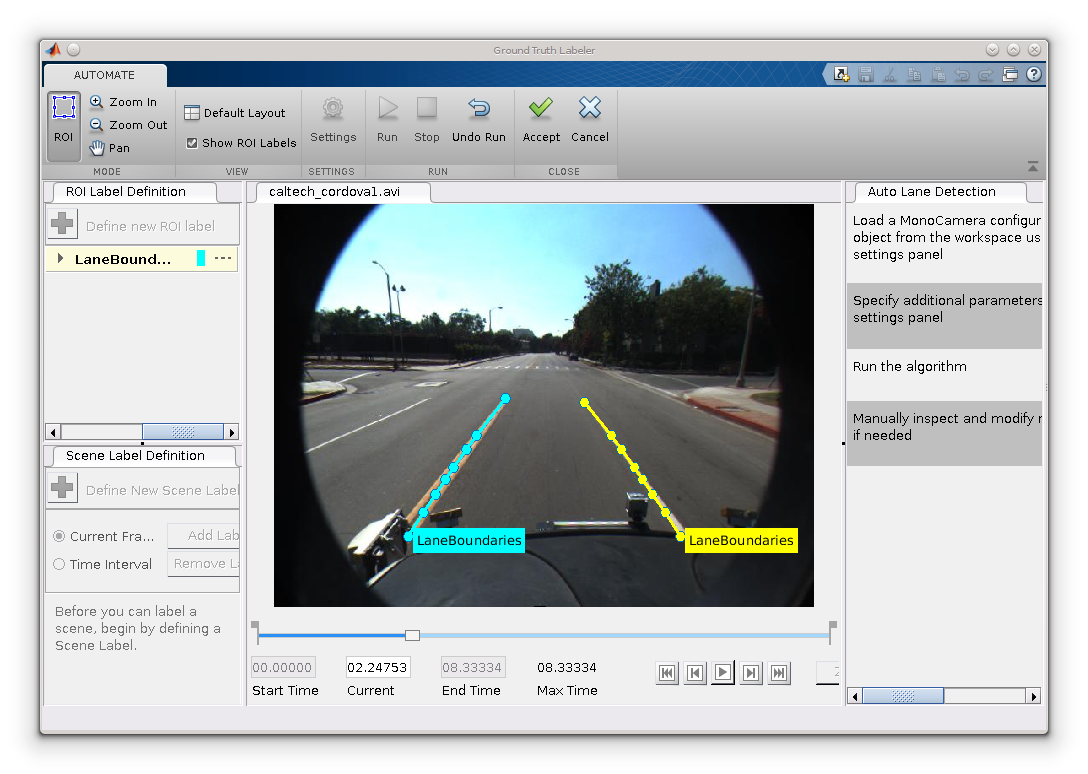

- Once you are satisfied with the lane boundaries for the entire video, click **Accept**.

The auto lane detection part of labeling the video is complete. You can proceed with labeling other objects of interest, save the session, or export the results of this labeling run.

## Conclusion

This example showed the steps to incorporate a lane detection algorithm into the [Ground Truth Labeler](docid:driving_ref#bvie3n7-1) app. You can extend this concept to other custom algorithms to simplify and extend the functionality of the app.

*Copyright 2016 The MathWorks, Inc.*